# 关于第一次编程作业的说明：

- 请注意完成编程作业中的讨论，可以通过注释、嵌入文本、额外文件等任意形式完成；

- 在第一次编程作业中如果使用工具箱，可以通过截图等形式提交结果；

- 为了简化大家的代码过程，我向大家提供了第一次编程作业的.mlx文件，里面提供了关于.mlx文件的说明；

- 大家仍然可以使用任意形式matlab代码完成第一次编程作业，并不限制大家一定需要使用该模版，但仍然需要大家注明题号；

感谢大家的配合！

# template

- 本文件已经对每道编程题目通过分节符分节，可以单独通过”运行节“命令执行一道题目（选中）的代码，或通过”运行“命令执行整个文件；

- 关于很多同学在.mlx中遇到的图像错位问题：主要原因是在单个脚本文件中，工作区和图像设定是始终向后保持的。在之前的题目中使用subplot()画多个子图，之后的题目中画图时会出现在之前的子图中，可以在每个题目的代码前通过clf命令清除图像窗口；

clear
clf

% (a)
x = 0:pi/100:2*pi;  
y = sin(x)

y =          0    0.0314    0.0628    0.0941    0.1253    0.1564    0.1874    0.2181    0.2487    0.2790    0.3090    0.3387    0.3681    0.3971    0.4258    0.4540    0.4818    0.5090    0.5358    0.5621    0.5878    0.6129    0.6374    0.6613    0.6845    0.7071    0.7290    0.7501    0.7705    0.7902    0.8090    0.8271    0.8443    0.8607    0.8763    0.8910    0.9048    0.9178    0.9298    0.9409    0.9511    0.9603    0.9686    0.9759    0.9823    0.9877    0.9921    0.9956    0.9980    0.9995


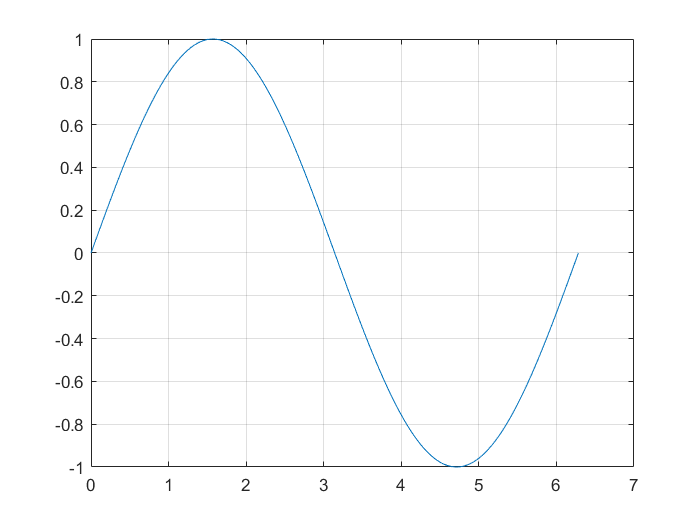

plot(x,y), grid;

% (b)
% 讨论分析

或通过内置文本讨论分析。如需插入公式，可以使用方程或LaTex方程 $F(s)=\int_0^\infty e^{-st} f(t) {\rm d}t$。

如需插入截图，直接粘贴即可。

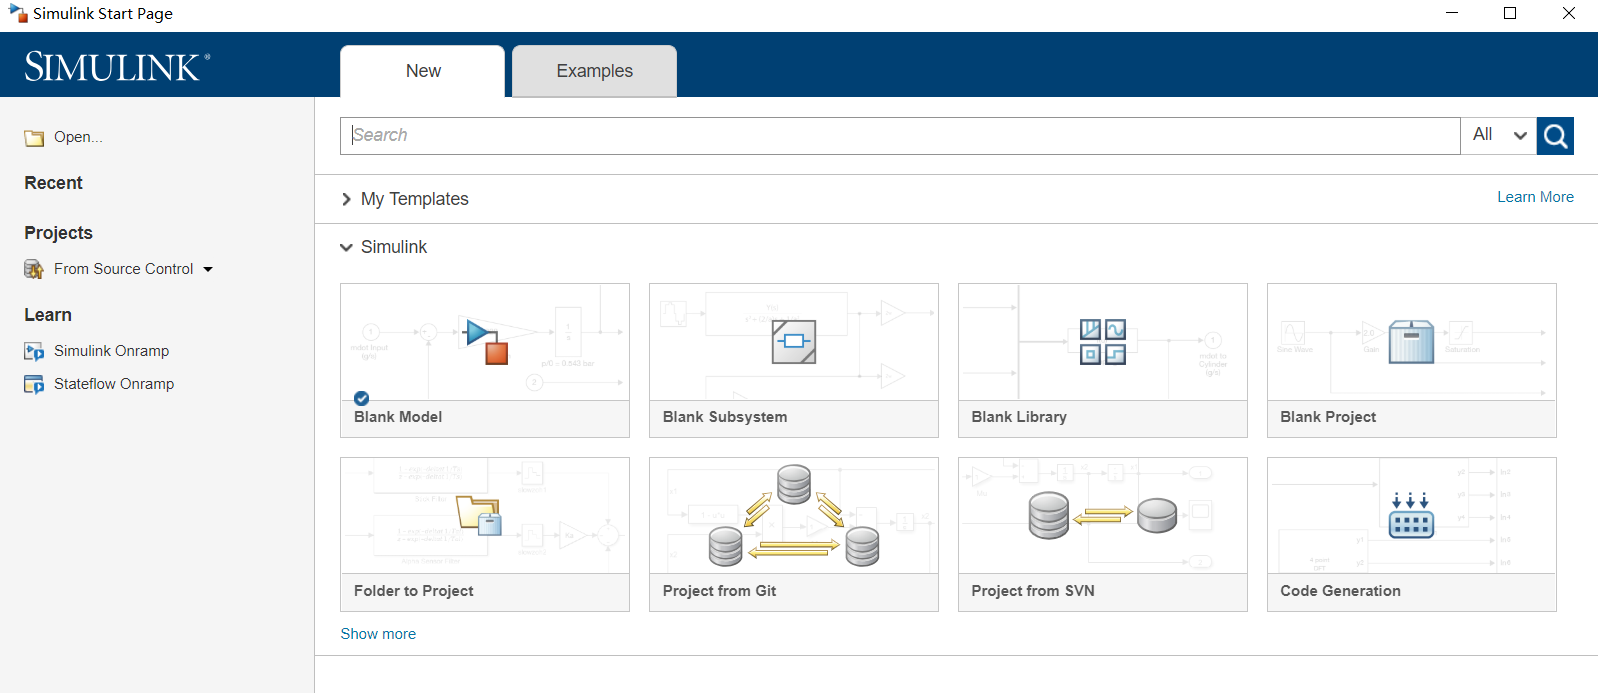

# 2-1

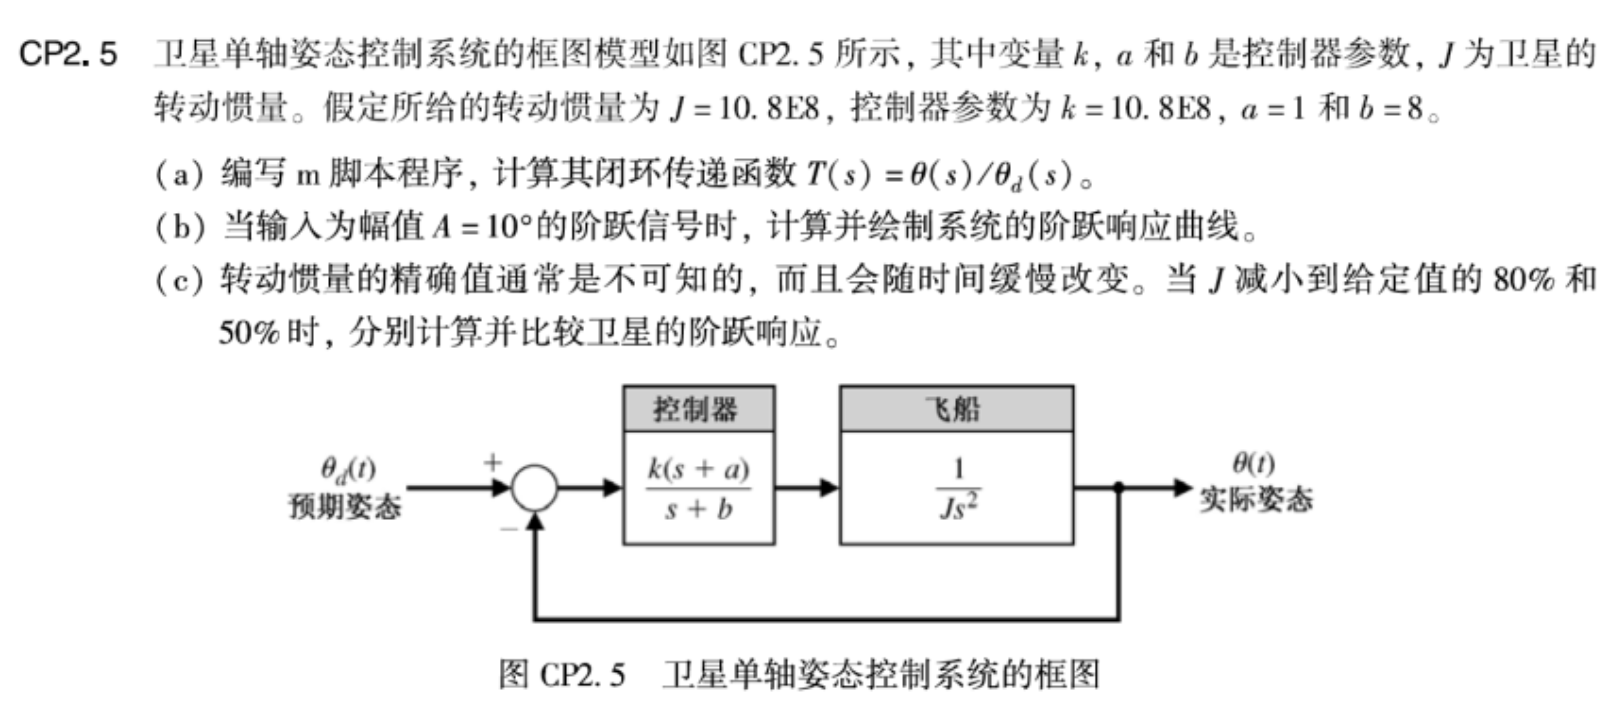

clf

% define parameters
J = 10.8E8;
k = 10.8E8;
a = 1;
b = 8;


% 3. 100%, 80% and 50% J
sys = get_sys_2_1(J, k, a, b)
t = 0:0.1:100;
y1 = get_y_2_1(get_sys_2_1(J, k, a, b), t);
y2 = get_y_2_1(get_sys_2_1(0.8 * J, k, a, b), t);
y3 = get_y_2_1(get_sys_2_1(0.5 * J, k, a, b), t);

sys =
 
                1.08e09 s + 1.08e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 1.08e09 s + 1.08e09
 
Continuous-time transfer function.



plot(t, y1, t, y2, ':', t, y3, '--'), grid
xlabel('Time (s)')
ylabel('theta (deg)')

由于函数只能放在末尾, 这里我就先注释掉, 然后把函数放末尾了...

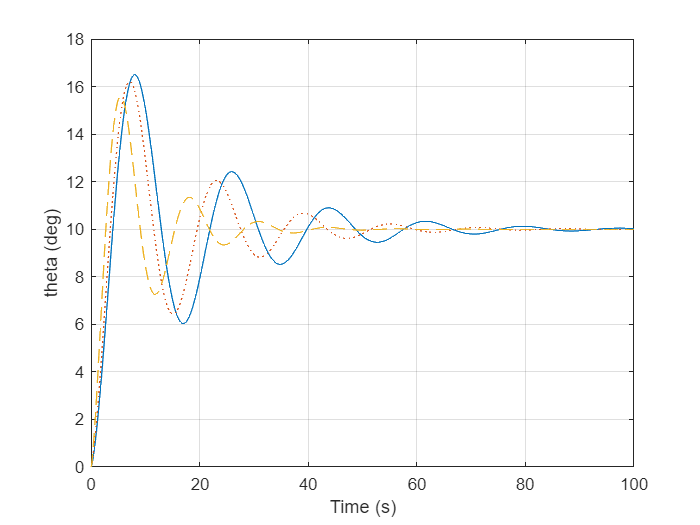

% % 1. calculate transfer function
% function sys = get_sys_2_1(J, k, a, b)
%     num1 = [k, k * a];
%     den1 = [1, b];

%     num2 = 1;
%     den2 = [J, 0, 0];

%     [num, den] = series(num1, den1, num2, den2);
%     [num, den] = feedback(num, den, 1, 1, -1);
%     sys = tf(num, den);
% end


% % 2. draw the curve with step sinal A = 10
% function y = get_y_2_1(sys, t)
%     opt = stepDataOptions('StepAmplitude', 10);
%     [y, ~] = step(sys, t, opt);
% end

# 2-2

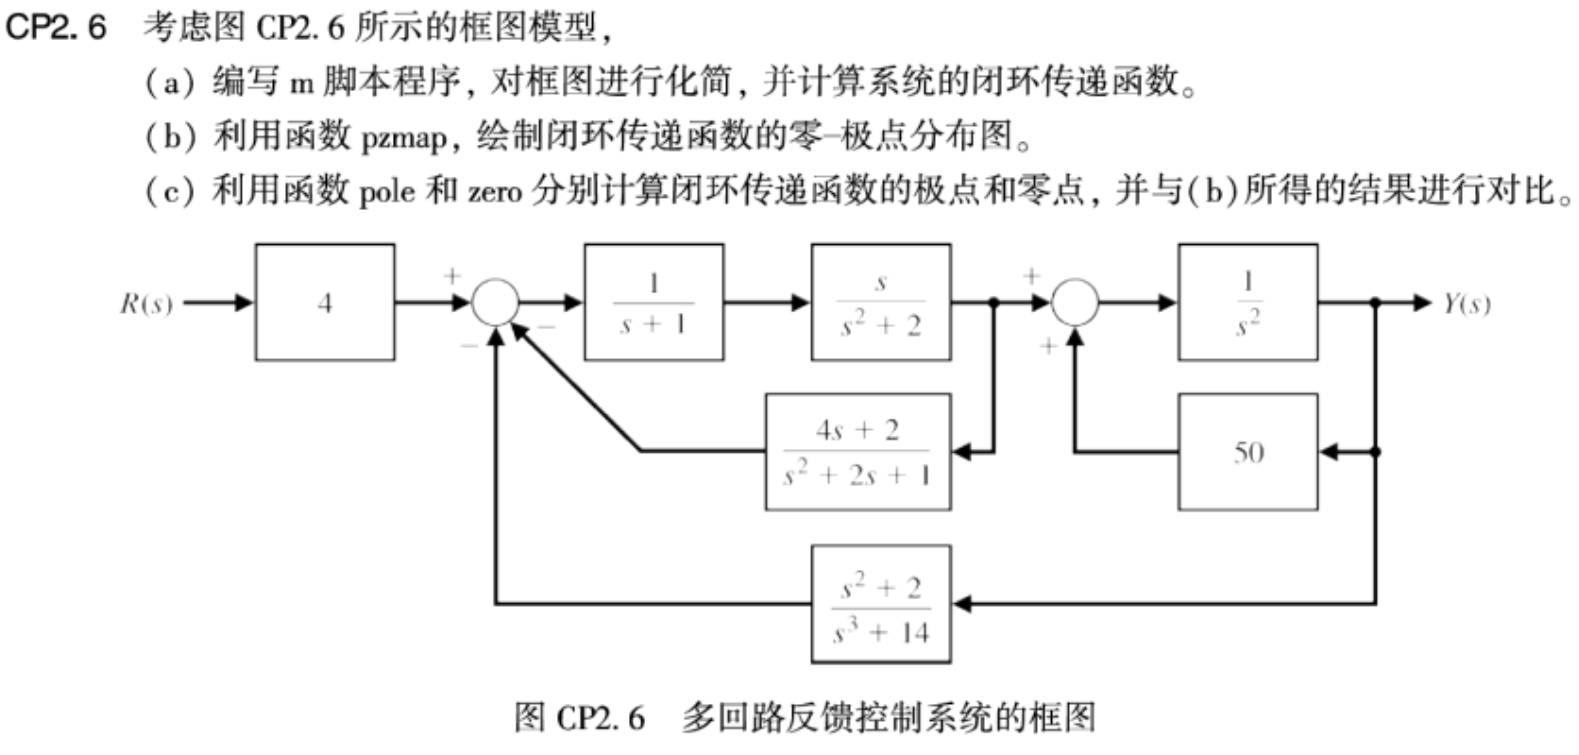

clf

% basic sys
num1 = 4; den1 = 1; sys1 = tf(num1, den1);
num2 = 1; den2 = [1 1]; sys2 = tf(num2, den2);
num3 = [1 0]; den3 = [1 0 2]; sys3 = tf(num3, den3);
num4 = 1; den4 = [1 0 0]; sys4 = tf(num4, den4);
num5 = [4 2]; den5 = [1 2 1]; sys5 = tf(num5, den5);
num6 = 50; den6 = 1; sys6 = tf(num6, den6);
num7 = [1 0 2]; den7 = [1 0 0 14]; sys7 = tf(num7, den7);


% 1. compose sys
sysc1 = series(sys2, sys3);
sysc2 = feedback(sysc1, sys5);
sysc3 = feedback(sys4, sys6, 1);
sysc4 = series(sysc2, sysc3);
sysc5 = feedback(sysc4, sys7);
sys = series(sys1, sysc5);
sys

sys =
 
                             4 s^6 + 8 s^5 + 4 s^4 + 56 s^3 + 112 s^2 + 56 s
  -----------------------------------------------------------------------------------------------------
  s^10 + 3 s^9 - 45 s^8 - 125 s^7 - 200 s^6 - 1177 s^5 - 2344 s^4 - 3485 s^3 - 7668 s^2 - 5598 s - 1400
 
Continuous-time transfer function.



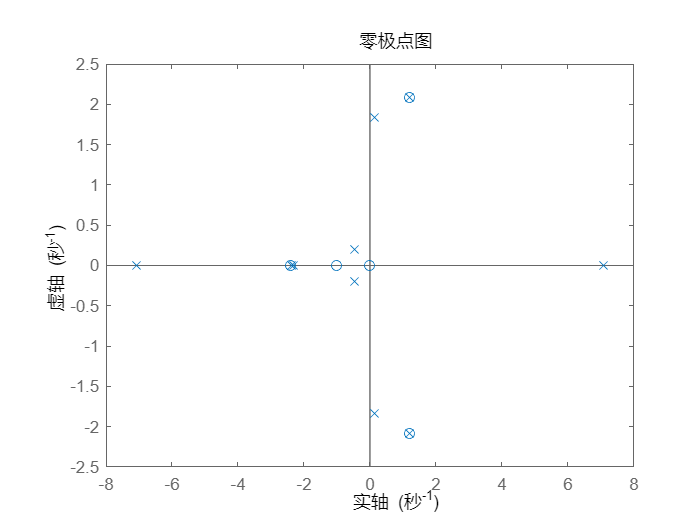

% 2. pzmap
pzmap(sys)

% 3. pole and zero
p = pole(sys);
z = zero(sys);
p

p =    7.0709 + 0.0000i
  -7.0713 + 0.0000i
   1.2051 + 2.0863i
   1.2051 - 2.0863i
   0.1219 + 1.8374i
   0.1219 - 1.8374i
  -2.3933 + 0.0000i
  -2.3333 + 0.0000i
  -0.4635 + 0.1997i
  -0.4635 - 0.1997i


z

z =    0.0000 + 0.0000i
   1.2051 + 2.0872i
   1.2051 - 2.0872i
  -2.4101 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


# 2-3

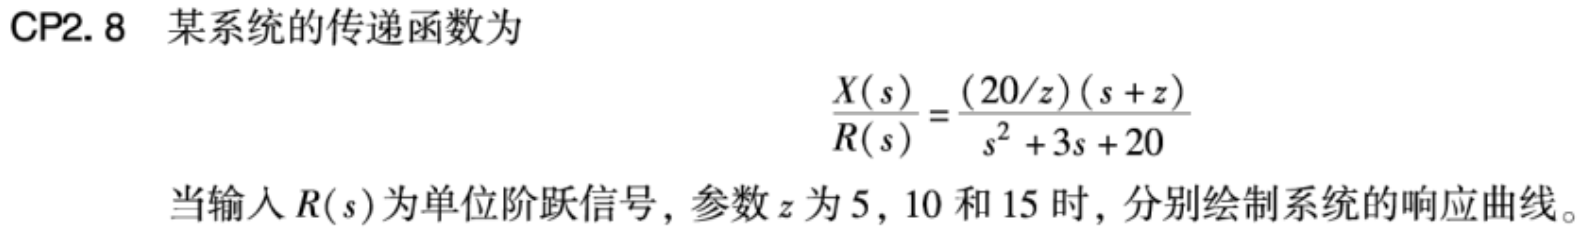

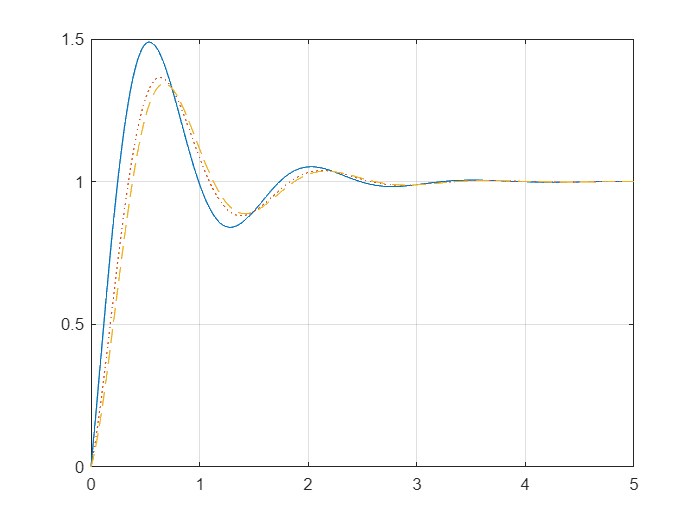

% z = 5, 10, 15
t = 0:0.005:5;
y1 = get_y_2_3(get_sys_2_3(5), t);
y2 = get_y_2_3(get_sys_2_3(10), t);
y3 = get_y_2_3(get_sys_2_3(15), t);     
plot(t, y1, t, y2, ':', t, y3, '--'), grid

由于函数只能放在末尾, 这里我就先注释掉, 然后把函数放末尾了...

% % 1. calculate transfer function
% function sys = get_sys_2_3(z)
%     num = [20 / z, 20];
%     den = [1, 3, 20];
%     sys = tf(num, den);
% end


% % 2. draw the curve with step sinal
% function y = get_y_2_3(sys, t)
%     [y, ~] = step(sys, t);
% end

# 2-4

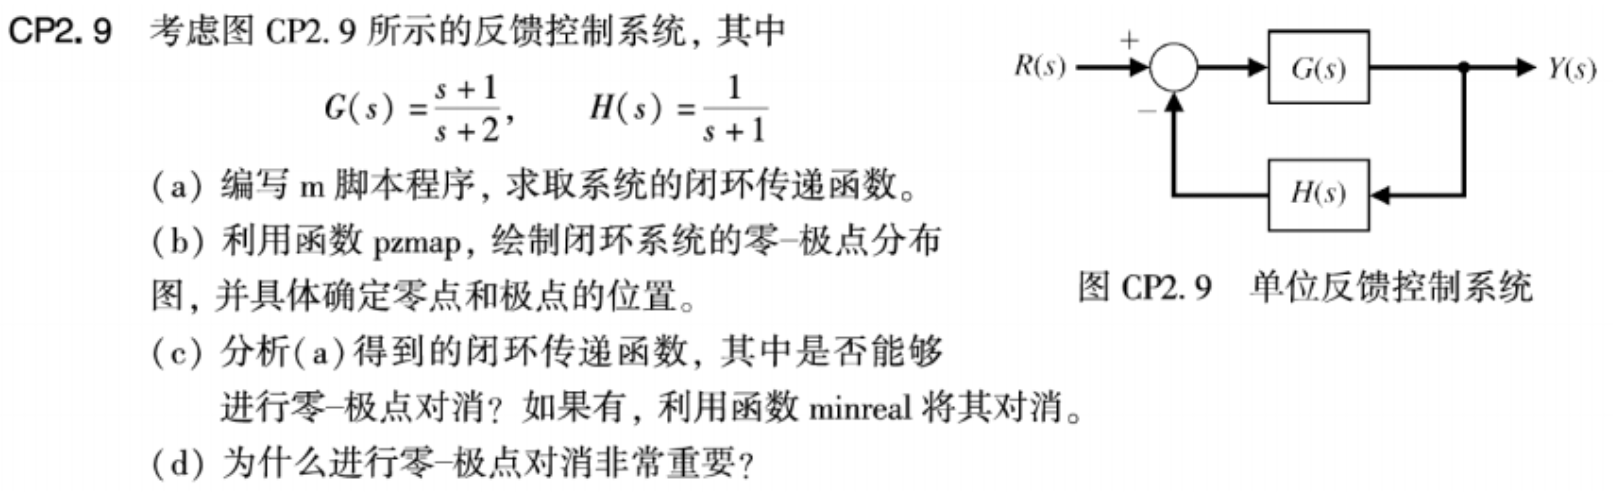

% 1.
num_g = [1 1]; den_g = [1 2]; sys_g = tf(num_g, den_g);
num_h = 1; den_h = [1 1]; sys_h = tf(num_h, den_h);
sys = feedback(sys_g, sys_h);
sys

sys =
 
  s^2 + 2 s + 1
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.



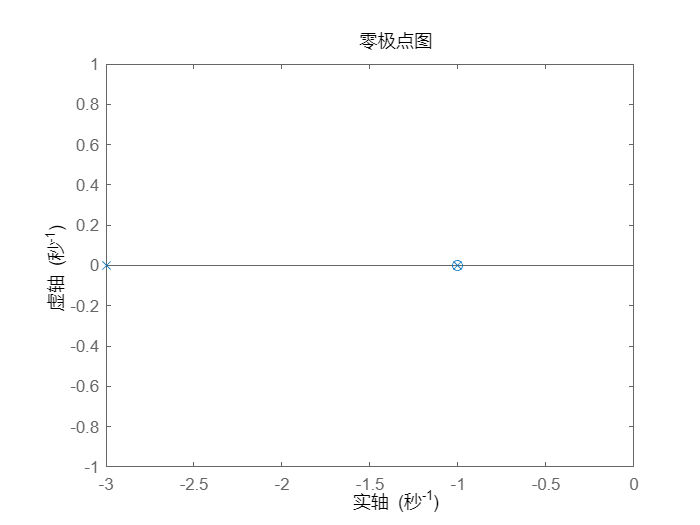

% 2.
pzmap(sys);

p = pole(sys);
z = zero(sys);
p

p =     -3
    -1


z

z =     -1
    -1


% 3.
sysm = minreal(sys);
sysm

sysm =
 
  s + 1
  -----
  s + 3
 
Continuous-time transfer function.



# 5-1

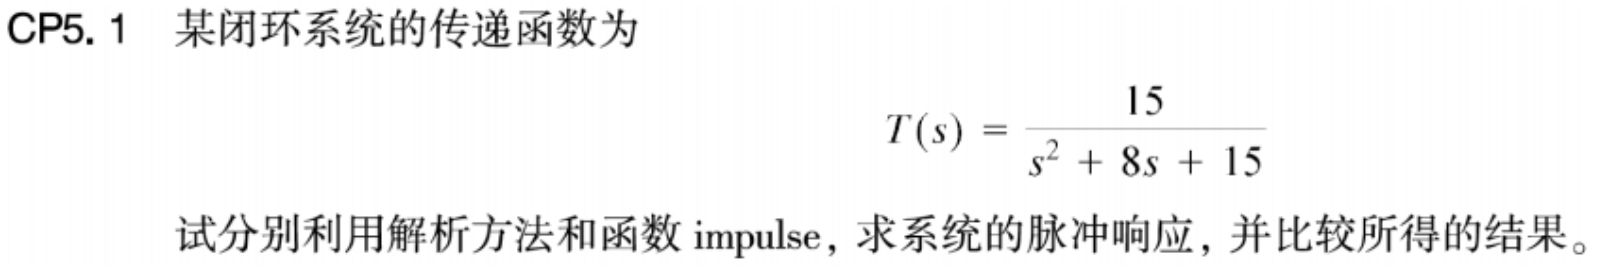

`由于脉冲信号的拉普拉斯变换为 `$R(s) = 1$`, 因此有`


$$\displaystyle
Y(s) = \frac{15}{s^{2}+8s+15}R(s) = \frac{15}{(s+3)(s+5)} = \frac{15}{2 (s + 3)} - \frac{15}{2 (s + 5)}$$


`因此, 进行逆拉普拉斯变换可得`


$$\displaystyle 
y(t) = \frac{15}{2}e^{-3t} - \frac{15}{2}e^{-5t}
$$


`此为解析方法的结果.`

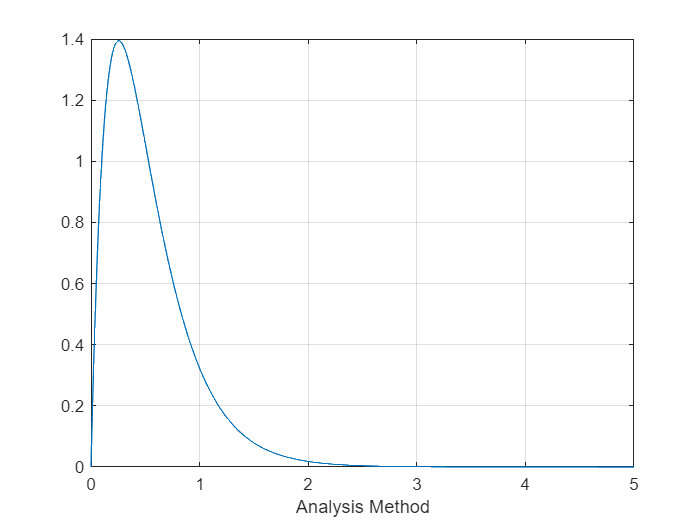

t = 0:0.005:5;
num = 15; den = [1 8 15]; sys = tf(num,den);

% y(t) = \frac{15}{2}e^{-3t} - \frac{15}{2}e^{-5t}
y1 = (15 / 2) * exp(-3 * t) - (15 / 2) * exp(-5 * t);
plot(t, y1), grid
xlabel('Analysis Method')

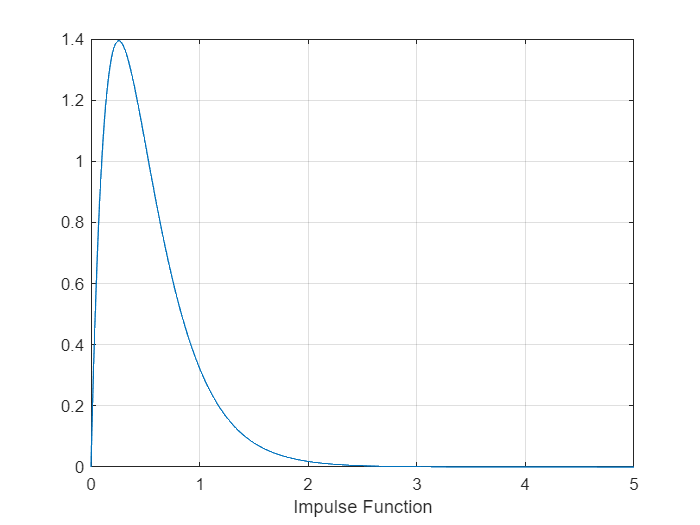

y2 = impulse(sys, t);
plot(t, y2), grid
xlabel('Impulse Function')

可以看出, 解析方法和函数 impulse 的结果是一致的.

# 5-2

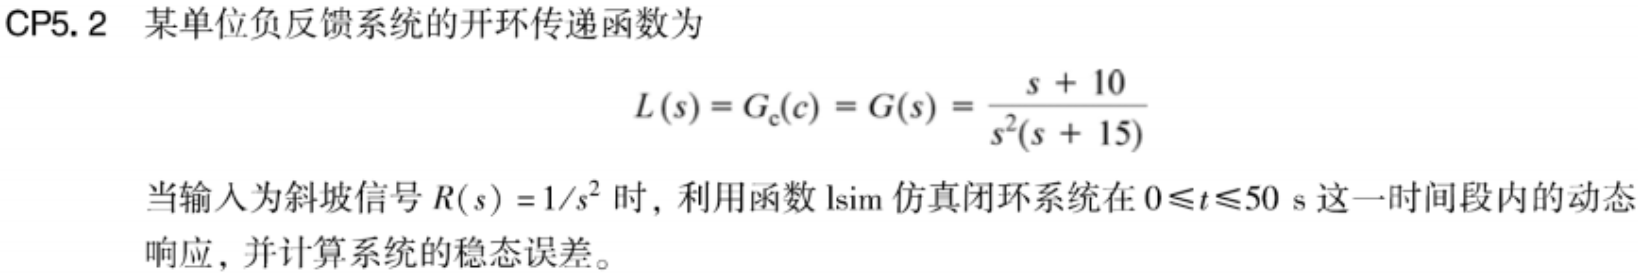

# 5-3

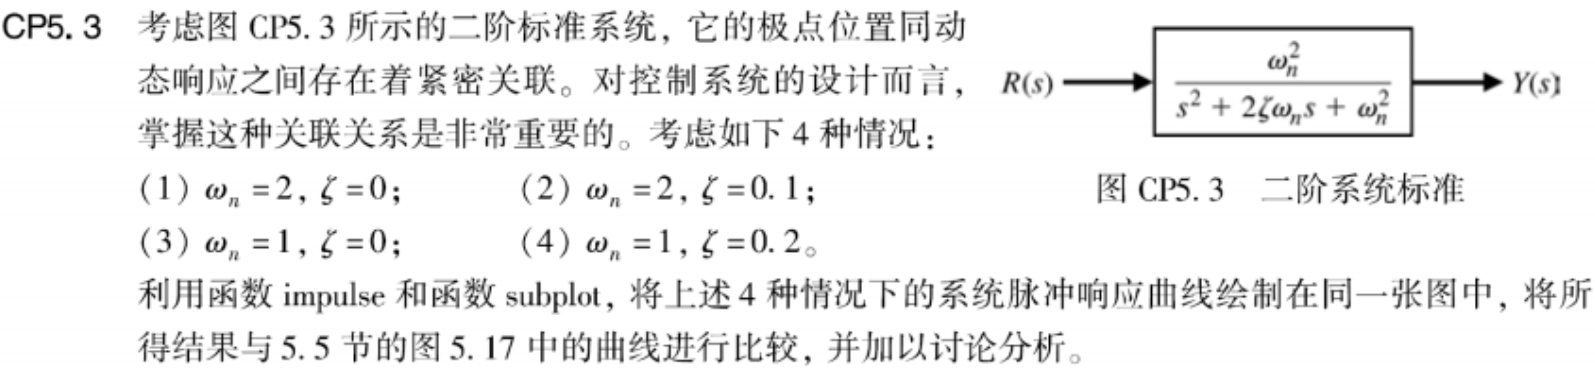

# 5-4

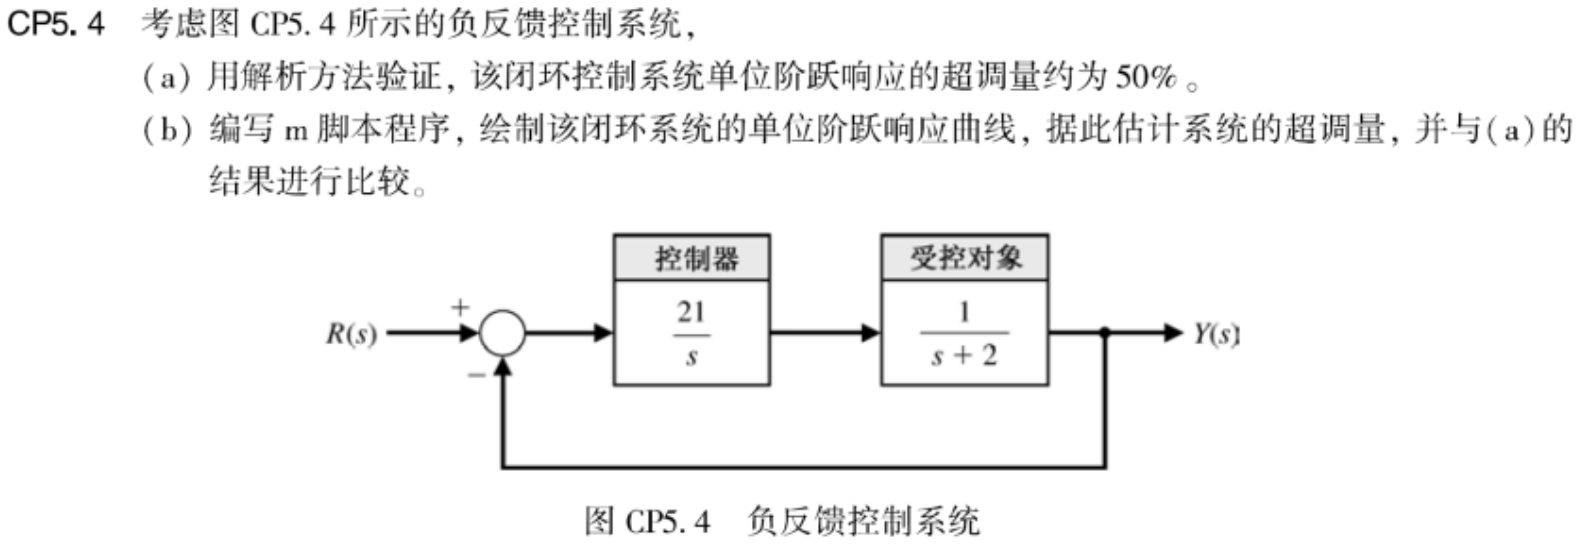

# 5-5

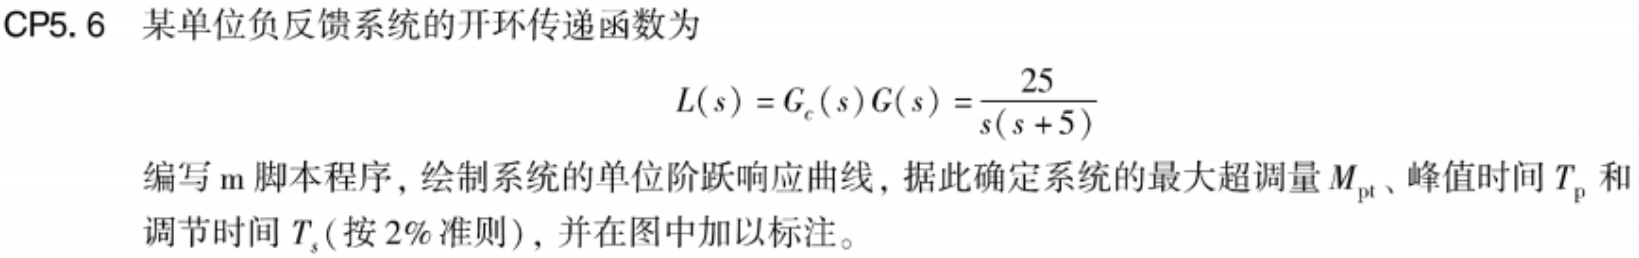

# 5-6

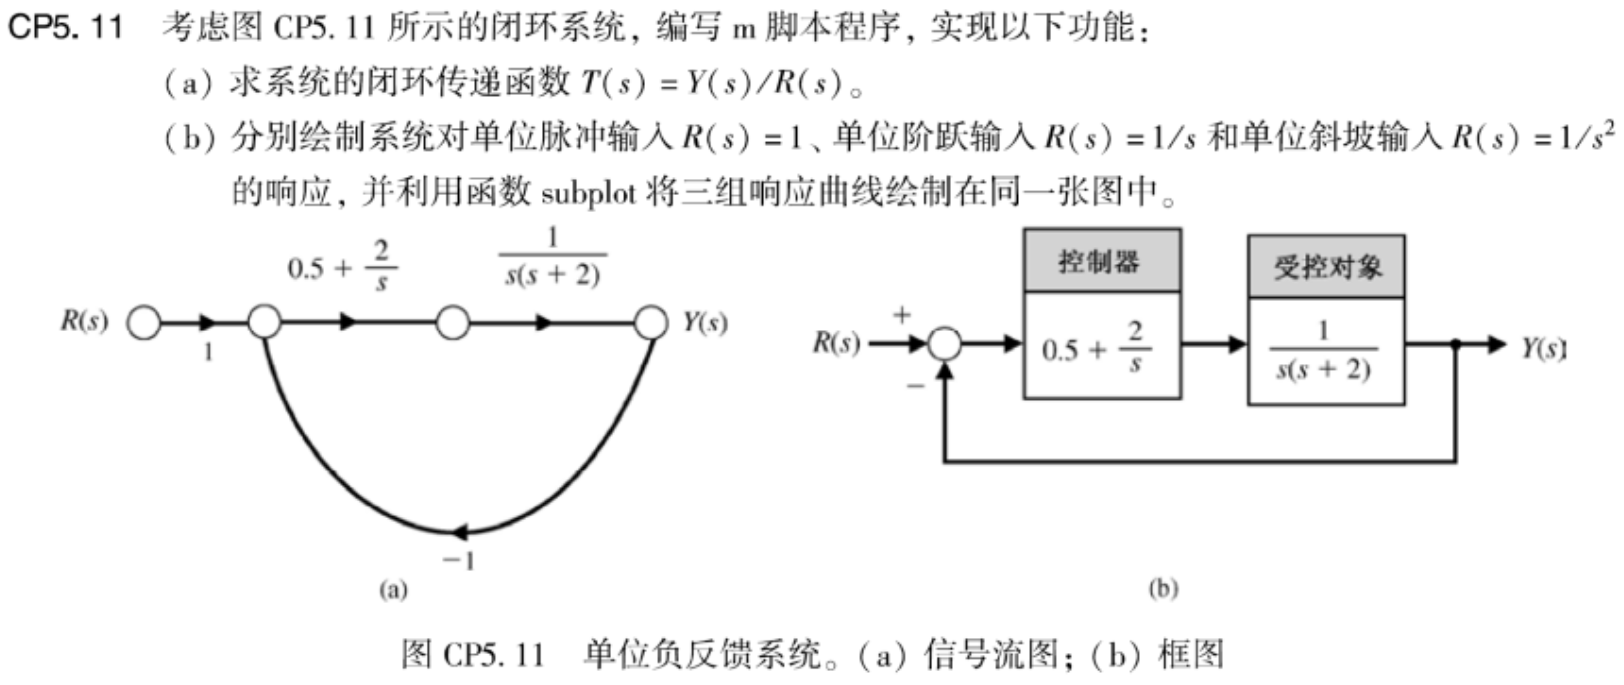

# 6-1

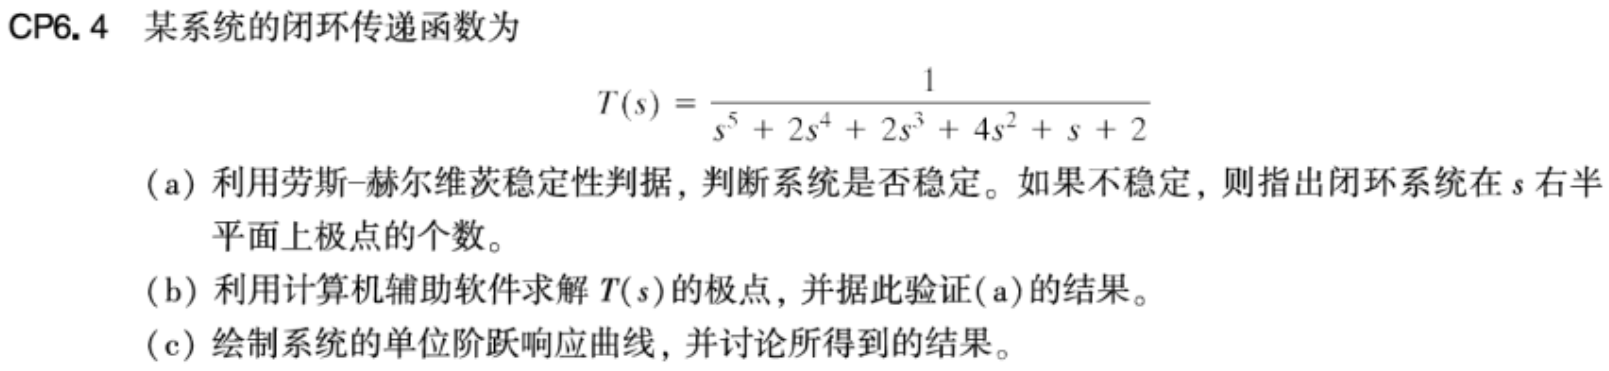

# 6-2

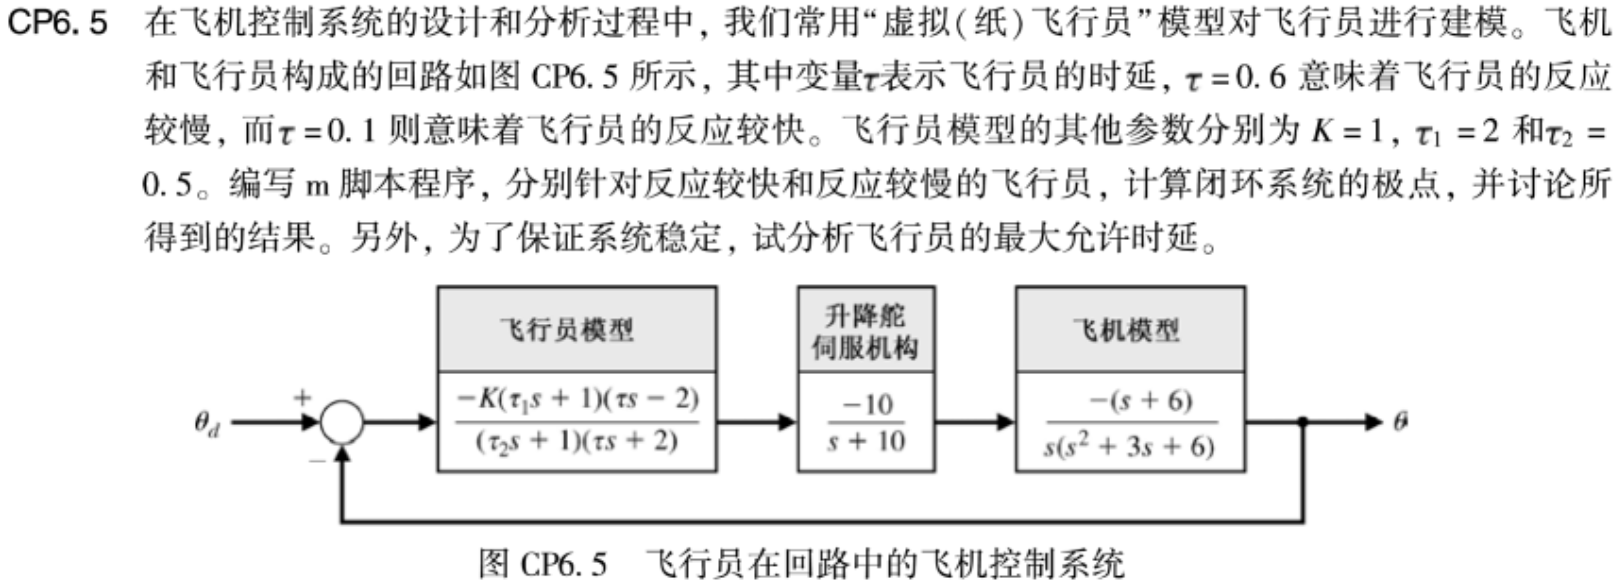

# 6-3

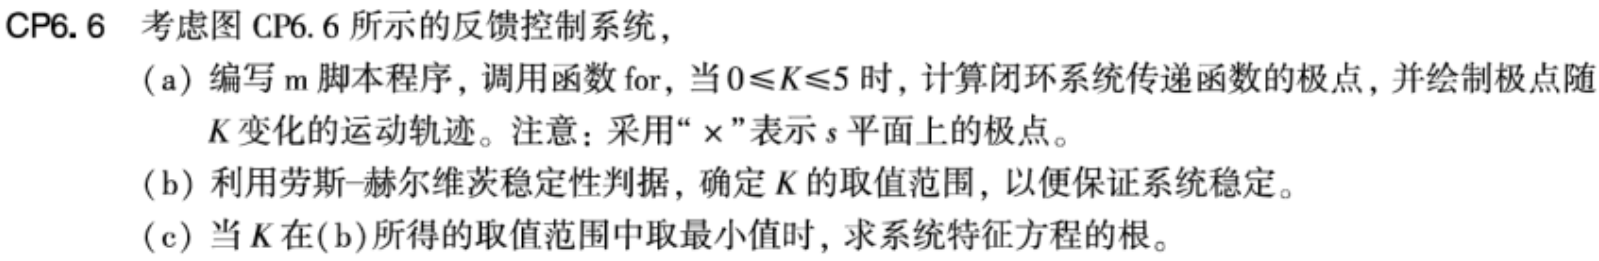

# 6-4

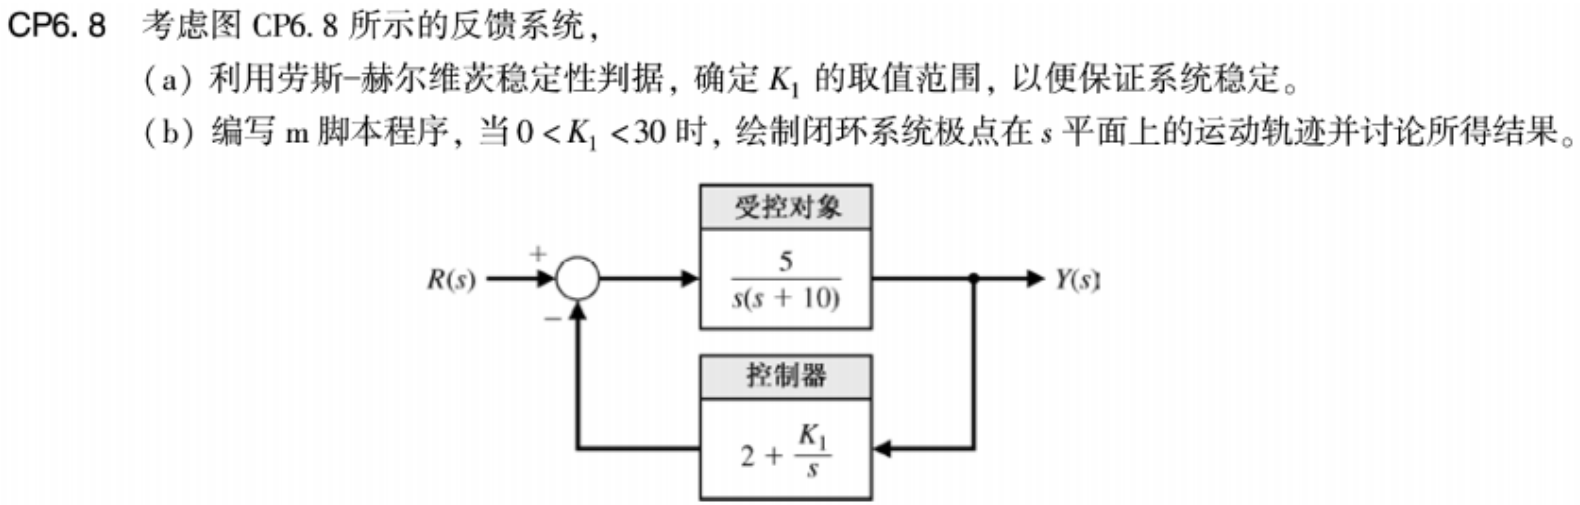

最后放了一些函数定义，因为脚本不允许把函数放在前面...

2.1

% 1. calculate transfer function
function sys = get_sys_2_1(J, k, a, b)
    num1 = [k, k * a];
    den1 = [1, b];
    num2 = 1;
    den2 = [J, 0, 0];

    [num, den] = series(num1, den1, num2, den2);
    [num, den] = feedback(num, den, 1, 1, -1);
    sys = tf(num, den);
end


% 2. draw the curve with step sinal A = 10
function y = get_y_2_1(sys, t)
    opt = stepDataOptions('StepAmplitude', 10);
    [y, ~] = step(sys, t, opt);
end

2.4

% 1. calculate transfer function
function sys = get_sys_2_3(z)
    num = [20 / z, 20];
    den = [1, 3, 20];
    sys = tf(num, den);
end


% 2. draw the curve with step sinal
function y = get_y_2_3(sys, t)
    [y, ~] = step(sys, t);
end